# Controllo della temperatura di una casa

## Descrizione del problema

L'obiettivo del progetto è regolare la temperatura di una casa utilizzando un controllore MPC. Si ipotizza che la casa non condivida alcun muro esterno con altre abitazioni, che i ﬂussi d'aria tra le stanze della casa siano trascurabili e che il riscaldamento della casa sia affidato a tre termosifoni, uno per ogni stanza. La pianta della casa in oggetto è mostrata nella figura seguente:

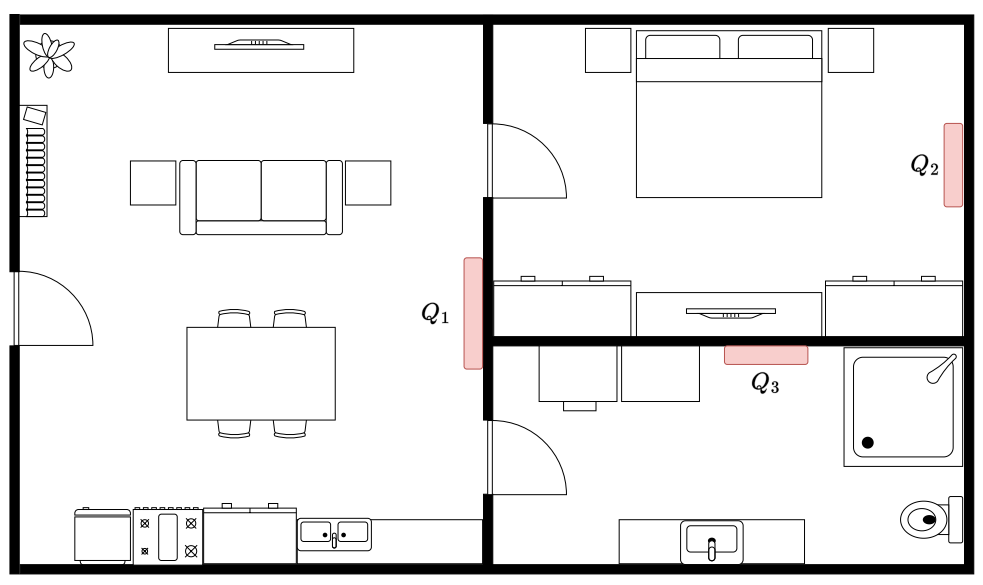

Figura 1: Planimetria della casa.

La dinamica della temperatura all’interno della casa è deﬁnita dalle equazioni seguenti:

$\begin{cases}
C_1\dot{T}_1(t) = Q_1(t) - k_{1,2}(t)(T_1(t)-T_2(t)) - k_{1,3}(t)(T_1(t)-T_3(t)) - k_{ext}(T_1(t)-T_{ext})\\
C_2\dot{T}_2(t) = Q_2(t) + k_{1,2}(t)(T_1(t)-T_2(t)) - k_{2,3}(t)(T_2(t)-T_3(t)) - k_{ext}(T_2(t)-T_{ext})\\
C_3\dot{T}_3(t) = Q_3(t) + k_{1,3}(t)(T_1(t)-T_3(t)) + k_{2,3}(t)(T_2(t)-T_3(t)) - k_{ext}(T_3(t)-T_{ext})\\
\dot{Q}_1 = (Q_{1,r}(t)-Q_1(t))/\tau_1 \\
\dot{Q}_2 = (Q_{2,r}(t)-Q_2(t))/\tau_2\\
\dot{Q}_3 = (Q_{3,r}(t)-Q_3(t))/\tau_3
\end{cases}$  con $k_{i,j} ={\bar{k} }_{i,j} +\frac{4}{1+e^{-0\ldotp 5{\left\|T_i \left(t\right)-T_j \left(t\right)\right\|}_2 } }$

Il significato delle grandezze presenti nelle precedenti equazioni è il seguente:

- $T_i\;[K]$ è la temperatura della i-esima stanza;

- $T_{ext}\;[K]$ è la temperatura esterna, ipotizzata costante.

- $C_i\;[J/s]$ è la capacità termica della i-esima stanza;

- $k_{i,j}\;[W/K]$ è un parametro che regola lo scambio di calore tra l’i-esima e la j-esima stanza;

- $k_{ext}\;[W/K]$ è un parametro che regola lo scambio di calore tra le stanze della casa e l’esterno;

- $Q_i\;[W]$ è la potenza termica dell’i-esimo termosifone;

- $Q_{i,r}\;[W]$ è la potenza termica di riferimento dell’i-esimo termosifone;

- $\tau_i\;[s]$ è la costante di tempo dell’i-esimo termosifone. 

I parametri noti sono riportati nella tabella seguente:


$$\matrix{
\textbf{Parametro} & \textbf{Valore} & \textbf{Unità}    \cr
C_1 		& 6800 		& J/s	        \cr
C_2			& 5600		& J/s		\cr
C_3	        	& 5100 		& J/s		\cr
\bar{k}_{1,2} 		& 15 		& W/K	        \cr
\bar{k}_{1,3}		& 20	         	& W/K		\cr
\bar{k}_{2,3}	       	& 15 		& W/K		\cr
k_{ext}	       	& 8 	        	& W/K		\cr
T_{ext}	       	& 278        	& K    		\cr
\tau_1 		& 400 		& s	                \cr
\tau_2		& 450		& s		        \cr
\tau_3        	& 450 		& s	        	\cr
}$$


Tabella 1: Parametri noti del sistema in esame.

La potenza erogata dai tre termosifoni è non-negativa e mai superiore ai 150W, mentre la temperatura all’interno delle tre stanze non deve mai scendere al di sotto dei 286K.

Gli ingressi controllati del sistema sono le potenze di riferimento dei tre termosifoni, $Q_{i,r}$, $i \in \{1,2,3\}$.

L’obiettivo del lavoro è progettare un controllore MPC in grado di portare il sistema dalla condizione iniziale $(T_1, T_2 , T_3 , Q_1 , Q_2 , Q_3 ) = (288, 288, 288, 0, 0, 0)$ all’equilibrio $(293, 293, 293, 120, 120, 120)$, rispettando sempre i vincoli, e simulare il funzionamento del sistema in anello chiuso. Il tempo minimo di campionamento, $T_s$, è pari ad $1\;s$.

## Parametri costanti del modello della casa

Inizialmente, si creano delle variabili per salvare tutti i parametri noti del modello.

clc
close all
clear
T_ext = 278; % [K], temperatura esterna ipotizzata costante
C = [6800 5600 5100]; % [J/s], capacità termica della i-esima stanza
k_bar = [15 20 15]; % [W/K], scambio di calore fra l'i-esima e la j-esima stanza 
k_ext = 8; % [W/K], scambio di calore fra le stanze e l'esterno
Q_ref = [150 150 150]; % [W], potenza termica di riferimento dell'i-esimo termosifone
tau = [400 450 450]; % [s], costante di tempo dell'i-esimo termosifone
x_eq = [293 293 293 120 120 120]';
x_ci = [288 288 288 0 0 0]';
Ts = 1; % [s], tempo di campionamento minimo

## Equazioni del sistema in variabili di stato

Prima di procedere ad analizzare il sistema, è necessario riscrivere le equazioni della sua dinamica nello spazio degli stati. Si definiscono il vettore degli stati, $\mathbf{x}$, ed il vettore degli ingressi, $\mathbf{u}$:

$\mathbf{x} = [x_1, x_2, x_3, x_4, x_5, x_6 ]'
:= [T_1, T_2, T_3, Q_1, Q_2, Q_3]'$, $\mathbf{x}\in \mathbb{R}^6$

$\mathbf{u} = [u_1, u_2, u_3]' := [Q_{1,r},\;Q_{2,r},\;Q_{3,r}]'$, $\mathbf{u}\in \mathbb{R}^3$

Il sistema diventa quindi:

$\begin{cases}
\dot{x}_1(t) = (x_4(t) - k_{1,2}(t)(x_1(t)-x_2(t)) - k_{1,3}(t)(x_1(t)-x_3(t)) - k_{ext}(x_1(t)-T_{ext}))/C_1\\
\dot{x}_2(t) = (x_5(t) + k_{1,2}(t)(x_1(t)-x_2(t)) - k_{2,3}(t)(x_2(t)-x_3(t)) - k_{ext}(x_2(t)-T_{ext})/C_2\\
\dot{x}_3(t) = (x_6(t) + k_{1,3}(t)(x_1(t)-x_3(t)) + k_{2,3}(t)(x_2(t)-x_3(t)) - k_{ext}(x_3(t)-T_{ext})/C_3\\
\dot{x}_4 = (u_1(t)-x_4(t))/\tau_1 \\
\dot{x}_5 = (u_2(t)-x_5(t))/\tau_2\\
\dot{x}_6 = (u_3(t)-x_6(t))/\tau_3
\end{cases}$ con $k_{i,j} ={\bar{k} }_{i,j} +\frac{4}{1+e^{-0\ldotp 5{\left\|x_i \left(t\right)-x_j \left(t\right)\right\|}_2 } }$

Le equazioni vengono scritte in Matlab utilizzando la notazione simbolica.

syms x1 x2 x3 x4 x5 x6 x1d x2d x3d x4d x5d x6d u1 u2 u3;
% Coefficienti k(i,j)
% Definizione dei vettori per poter calcolare correttamente le norme
x1_vect = [x1;0;0];
x2_vect = [0;x2;0];
x3_vect = [0;0;x3];
k12 = k_bar(1)+(4/(1+exp(-0.5*norm(x1_vect-x2_vect,2))));
k13 = k_bar(2)+(4/(1+exp(-0.5*norm(x1_vect-x3_vect,2))));
k23 = k_bar(3)+(4/(1+exp(-0.5*norm(x2_vect-x3_vect,2))));
% Equazioni della dinamica del sistema
eq1 = x1d == (x4 -k12*(x1-x2) -k13*(x1-x3) -k_ext*(x1-T_ext))/C(1);
eq2 = x2d == (x5 +k12*(x1-x2) -k23*(x2-x3) -k_ext*(x2-T_ext))/C(2);
eq3 = x3d == (x6 +k13*(x1-x3) +k23*(x2-x3) -k_ext*(x3-T_ext))/C(3);
eq4 = x4d == (u1-x4)/tau(1);
eq5 = x5d == (u2-x5)/tau(2);
eq6 = x6d == (u3-x6)/tau(3);
equazioni = [eq1;eq2;eq3;eq4;eq5;eq6]

$$equazioni = \begin{array}{l} \left(\begin{array}{c} \mathrm{x1d}=\frac{x_{4}}{6800}-\frac{x_{1}}{850}-\frac{\sigma_{3}}{6800}-\frac{\sigma_{1}}{6800}+\frac{139}{425}\\ \mathrm{x2d}=\frac{x_{5}}{5600}-\frac{x_{2}}{700}+\frac{\sigma_{3}}{5600}-\frac{\sigma_{2}}{5600}+\frac{139}{350}\\ \mathrm{x3d}=\frac{x_{6}}{5100}-\frac{2\,x_{3}}{1275}+\frac{\sigma_{2}}{5100}+\frac{\sigma_{1}}{5100}+\frac{556}{1275}\\ \mathrm{x4d}=\frac{u_{1}}{400}-\frac{x_{4}}{400}\\ \mathrm{x5d}=\frac{u_{2}}{450}-\frac{x_{5}}{450}\\ \mathrm{x6d}=\frac{u_{3}}{450}-\frac{x_{6}}{450} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\left(\frac{4}{{\mathrm{e}}^{-\frac{\sqrt{{\left|x_{1}\right|}^{2}+{\left|x_{3}\right|}^{2}}}{2}}+1}+20\right)\,\left(x_{1}-x_{3}\right)\\ \sigma_{2}=\left(\frac{4}{{\mathrm{e}}^{-\frac{\sqrt{{\left|x_{2}\right|}^{2}+{\left|x_{3}\right|}^{2}}}{2}}+1}+15\right)\,\left(x_{2}-x_{3}\right)\\ \sigma_{3}=\left(\frac{4}{{\mathrm{e}}^{-\frac{\sqrt{{\left|x_{1}\right|}^{2}+{\left|x_{2}\right|}^{2}}}{2}}+1}+15\right)\,\left(x_{1}-x_{2}\right) \end{array}$$

## Vincoli su stato e ingresso

Successivamente, si definiscono i vincoli esistenti su stato e ingresso del sistema.

x_min_temp = 268.*ones(3,1); % Vincolo di minimo sulla temperatura dell'i-esima stanza
x_min_power = zeros(3,1); % Vincolo di minimo sulla potenza dell'i-esimo termosifone
x_min = [x_min_temp;x_min_power]; % Vincolo di minimo sullo stato
x_max_temp = inf.*ones(3,1); % Vincolo di massimo sulla temperatura dell'i-esima stanza
x_max_power = 150.*ones(3,1); % Vincolo di massimo sulla potenza dell'i-esimo termosifone
x_max = [x_max_temp;x_max_power]; % Vincolo di massimo sullo stato
u_min = zeros(3,1); % Vincolo di minimo sulla potenza dell'i-esimo termosifone
u_max = 150.*ones(3,1); % Vincolo di minimo sulla potenza dell'i-esimo termosifone

## Punti di equilibrio

Dalle equazioni sappiamo che il sistema non è lineare, in quanto alcune variabili di stato compaiono nell'esponenziale. Sarà perciò necessario linearizzare il sistema attorno ad un punto di equilibrio. Per calcolare gli ingressi di equilibrio, si azzera la dinamica del sistema, ponendo a zero le derivate degli stati, e si calcolano le soluzioni del sistema di equazioni sostituendo il punto di equilibrio.  

% Azzeramento della dinamica
x1d = 0;
x2d = 0;
x3d = 0;
x4d = 0;
x5d = 0;
x6d = 0;

% Sostituzione dei valori noti, ovvero il punto di equilibrio
x1 = x_eq(1);
x2 = x_eq(2);
x3 = x_eq(3);
x4 = x_eq(4);
x5 = x_eq(5);
x6 = x_eq(6);
equazioni_equilibrio = subs(equazioni);

% Ottenimento degli ingressi di equilibrio, u_eq
res = solve(equazioni_equilibrio)

res = struct with fields:
    u1: 120
    u2: 120
    u3: 120


u_eq = [double(res.u1) double(res.u2) double(res.u3)]';

## Sistema linearizzato

Prima di progettare il regolatore MPC, è necessario linearizzare il sistema attorno al punto di equilibrio calcolato nella sezione precedente, così da calcolare le matrici A e B del sistema linearizzato.

syms x1 x2 x3 x4 x5 x6 u1 u2 u3
f1 = (x4 -k12*(x1-x2) -k13*(x1-x3) -k_ext*(x1-T_ext))/C(1);
f2 = (x5 +k12*(x1-x2) -k23*(x2-x3) -k_ext*(x2-T_ext))/C(2);
f3 = (x6 +k13*(x1-x3) +k23*(x2-x3) -k_ext*(x3-T_ext))/C(3);
f4 = (u1-x4)/tau(1);
f5 = (u2-x5)/tau(2);
f6 = (u3-x6)/tau(3);
sistema = [f1;f2;f3;f4;f5;f6];

% Calcolo delle derivate parziali rispetto ad ogni stato
sistema_lin(:,1) = diff(sistema,x1);
sistema_lin(:,2) = diff(sistema,x2);
sistema_lin(:,3) = diff(sistema,x3);
sistema_lin(:,4) = diff(sistema,x4);
sistema_lin(:,5) = diff(sistema,x5);
sistema_lin(:,6) = diff(sistema,x6);
sistema_lin;

% Calcolo delle derivate parziali rispetto ad ogni ingresso
ingresso_lin(:,1) = diff(sistema,u1);
ingresso_lin(:,2) = diff(sistema,u2);
ingresso_lin(:,3) = diff(sistema,u3);
ingresso_lin;

% Sostituzione del punto di equilibrio
x1 = x_eq(1);
x2 = x_eq(2);
x3 = x_eq(3);
x4 = x_eq(4);
x5 = x_eq(5);
x6 = x_eq(6);
u1 = u_eq(1);
u2 = u_eq(2);
u3 = u_eq(3);
A_ct = subs(sistema_lin)

$$A\_ct = \begin{array}{l} \left(\begin{array}{cccccc} -\frac{1}{850\,\sigma_{2}}-\frac{43}{6800} & \frac{1}{1700\,\sigma_{2}}+\frac{3}{1360} & \frac{1}{1700\,\sigma_{2}}+\frac{1}{340} & \frac{1}{6800} & 0 & 0\\ \sigma_{1} & -\frac{1}{700\,\sigma_{2}}-\frac{19}{2800} & \sigma_{1} & 0 & \frac{1}{5600} & 0\\ \frac{1}{1275\,\sigma_{2}}+\frac{1}{255} & \frac{1}{1275\,\sigma_{2}}+\frac{1}{340} & -\frac{2}{1275\,\sigma_{2}}-\frac{43}{5100} & 0 & 0 & \frac{1}{5100}\\ 0 & 0 & 0 & -\frac{1}{400} & 0 & 0\\ 0 & 0 & 0 & 0 & -\frac{1}{450} & 0\\ 0 & 0 & 0 & 0 & 0 & -\frac{1}{450} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{1}{1400\,\sigma_{2}}+\frac{3}{1120}\\ \sigma_{2}={\mathrm{e}}^{-\frac{\sqrt{171698}}{2}}+1 \end{array}$$

B_ct = subs(ingresso_lin)

$$B\_ct = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0\\ \frac{1}{400} & 0 & 0\\ 0 & \frac{1}{450} & 0\\ 0 & 0 & \frac{1}{450} \end{array}\right)$$

## Autovalori del sistema linearizzato a tempo continuo

Prima di andare a discretizzare il sistema, si analizzano gli autovalori della matrice di stato, A, per studiare la natura del sistema in esame. Questo passaggio è utile sia per capire il comportamento del sistema, che per scegliere il metodo di discretizzazione più adatto.

lambda_i = eig(A_ct);
real_lambda_i = double(real(lambda_i))

real_lambda_i =    -0.0025
   -0.0022
   -0.0022
   -0.0014
   -0.0110
   -0.0134


imag_lambda_i = double(imag(lambda_i([5,6])))

imag_lambda_i = 1.0e-73 *

   -0.2819
    0.2487


Il sistema ha quattro autovalori reali negativi e una coppia di autovalori complessi coniugati con parte reale negativa, di conseguenza è asintoticamente stabile. Tuttavia, questi valori sono molto prossimi all'asse immaginario, quindi significa che sono molto lenti. La parte immaginaria degli autovalori complessi coniugati è praticamente nulla, ciò significa che la dinamica del sistema non è soggetta ad oscillazioni. 

Per progettare il controllore, il sistema deve essere completamente raggiungibile. Verifichiamo quest'ipotesi calcolando il rango della matrice di raggiungibilità del sistema.

Mr_ct = ctrb(A_ct,B_ct);
rk_Mr_ct = rank(Mr_ct)

rk_Mr_ct = 6

Dato che il rango della matrice di raggiungibilità $M_r$ è pari alla dimensione dello stato, $n$, ovvero 6, si può concludere che il sistema è completamente raggiungibile.

## Matrici del sistema linearizzato a tempo discreto

Dato che i controllori lavorano a tempo discreto, è necessario discretizzare le matrici del sistema. Le matrici A e B sono già note a tempo continuo, mentre C e D no. Visto che per il corretto funzionamento del controllore MPC è necessario retroazionare lo stato, si ipotizza che questa misura sia disponibile, ovvero che lo stato sia accessibile, quindi la matrice C è una matrice identità di dimensioni 6x6. Per quanto riguarda la matrice D, sarà una matrice di zeri di dimensioni 6x3, perché si ipotizza che le misure non dipendano dagli ingressi. Una volta ottenuto il sistema a tempo continuo, si ricaverà il sistema a tempo discreto con l'apposito comando di Matlab. Si sceglie di utilizzare il metodo di Tustin, così che il semipiano reale negativo venga mappato nel cerchio di raggio 1 centrato nell'origine. Dato che il sistema è asintoticamente stabile, si poteva utilizzare anche il metodo di Eulero in avanti. 

C_ct = eye(6);
D_ct = zeros(6,3);
continuous_time_ss = ss(double(A_ct),double(B_ct),C_ct,D_ct);
discrete_time_ss = c2d(continuous_time_ss,Ts,'tustin');
A = discrete_time_ss.A;
B = discrete_time_ss.B;

Per verificare la correttezza dell'operazione di discretizzazione, si possono analizzare gli autovalori della matrice A e il rango della matrice di raggiungibilità a tempo discreto.

lambda_i_dt = eig(A)

lambda_i_dt =     0.9986
    0.9891
    0.9867
    0.9975
    0.9978
    0.9978


Mr = ctrb(A,B);
rk_Mr = rank(Mr)

rk_Mr = 6

I risultati ottenuti a tempo discreto sono coerenti con quelli ottenuti a tempo continuo: gli autovalori hanno valore molto prossimo all'unità, ciò significa che sono lenti, inoltre il rango della matrice di raggiungibilità rimane pari alla dimensione dello stato, che 6, perciò il sistema è completamente raggiungibile.

## Espressione dei vincoli nelle coordinate del sistema linearizzato

Il progetto del controllore MPC è legato al punto di equilibrio scelto, perché questo viene visto come se fosse l'origine del sistema. Per questo motivo, si devono riesprimere i vincoli e la condizione iniziale nelle coordinate del sistema linearizzato.

x_ci_mpc = x_ci-x_eq;
u_eq_mpc = u_eq-u_eq;
x_eq_mpc = zeros(6,1);
x_max_mpc = x_max-x_eq;
x_min_mpc = x_min-x_eq;
u_max_mpc = u_max-u_eq;
u_min_mpc = u_min-u_eq;

## Calcolo del Control Invariant Set

Un ingredente necessario per progettare il controllore MPC è il Control Invariant Set (CIS). Le dimensioni di questo insieme dipendono dalla scelta delle matrici Q ed R del costo quadratico. Il CIS è calcolato iterativamente, ma prima bisogna esprimere i vincoli del sistema nella forma $H_x\;x \le hx, H_u\;u \le hu$.

% Valori sulla diagonale delle matrici quadrate Q ed R
Q_val = 1;
R_val = 1;
Q = Q_val.*eye(6);
R = R_val.*eye(3);
% Vincoli su stato e ingresso, espressi nella forma di <=
Hx = [eye(6); -eye(6)];
hx = [x_max_mpc;-x_min_mpc];
Hu = [eye(3); -eye(3)];
hu = [u_max_mpc;-u_min_mpc];
% Chiamata alla funzione che calcola il CIS
[G,g] = cis(A,B,x_eq_mpc,u_eq_mpc,Hx,hx,Hu,hu,Q,R);
CIS = Polyhedron(G,g);
% Stampa di alcune informazioni riguardanti il CIS appena calcolato
CIS.display()

Polyhedron in R^6 with representations:
    H-rep (redundant)   : Inequalities  15 | Equalities   0
    V-rep               : Unknown (call computeVRep() to compute)
Functions : none


CIS.isBounded()

ans = logical
   1


CIS.isEmptySet()

ans = logical
   0


CIS.isFullDim()

ans = logical
   1


Dato che non è possibile visualizzare il grafico del poliedro, in quanto appartenente allo spazio 6D, si utilizzano delle funzioni di MPT3 per ricavare alcune proprietà di questo poliedro. Alcuni vincoli sono ridondanti, la regione individuata non è vuota ed è limitata, inoltre ha dimensione pari alla dimensione dello stato, che è 6. 

## Formulazione del problema quadratico

...

% Orizzonte di predizione
N = 10;
nx = size(A,1);
nu = size(B,2);

% Controllo aggressivo
Q_val = 10;
R_val = 0.1;
Q_hard = Q_val.*Q;
R_hard = R_val.*R;

A_italic = zeros(nx*(N+1),nx);
%% B_italic = zeros(nx*(N+1),nu*N);
for i = 0:1:N
    if(i==0)
        A_italic = eye(nx);
    else
        A_italic = [A_italic;A.^i];
        %% B_italic(:,nx*i+1:2*nx*i) = [A^(i)*B];
    end
end
%% B_italic
% A_italic_1 = [eye(6); A; A.^2; A.^3; A.^4; A.^5; A.^6; A.^7; A.^8; A.^9; A.^10];
B_italic = [zeros(6,3*N);
    B zeros(6,3*(N-1));
    A^(N-9)*B B zeros(6,3*(N-2));
    A^(N-8)*B A^(N-9)*B B zeros(6,3*(N-3));
    A^(N-7)*B A^(N-8)*B A^(N-9)*B B zeros(6,3*(N-4));
    A^(N-6)*B A^(N-7)*B A^(N-8)*B A^(N-9)*B B zeros(6,3*(N-5));
    A^(N-5)*B A^(N-6)*B A^(N-7)*B A^(N-8)*B A^(N-9)*B B zeros(6,3*(N-6));
    A^(N-4)*B A^(N-5)*B A^(N-6)*B A^(N-7)*B A^(N-8)*B A^(N-9)*B B zeros(6,3*(N-7));
    A^(N-3)*B A^(N-4)*B A^(N-5)*B A^(N-6)*B A^(N-7)*B A^(N-8)*B A^(N-9)*B B zeros(6,3*(N-8));
    A^(N-2)*B A^(N-3)*B A^(N-4)*B A^(N-5)*B A^(N-6)*B A^(N-7)*B A^(N-8)*B A^(N-9)*B B zeros(6,3*(N-9));
    A^(N-1)*B A^(N-2)*B A^(N-3)*B A^(N-4)*B A^(N-5)*B A^(N-6)*B A^(N-7)*B A^(N-8)*B A^(N-9)*B B];
[K,P] = dlqr(A,B,Q,R);
Q_italic_hard = [diag([diag(Q_hard); diag(Q_hard); diag(Q_hard); diag(Q_hard); diag(Q_hard); diag(Q_hard); diag(Q_hard); diag(Q_hard); diag(Q_hard); diag(Q_hard); diag(P)])]; %% se P non è diagonale, modificare diag(P)
R_italic_hard = [diag([diag(R_hard); diag(R_hard); diag(R_hard); diag(R_hard); diag(R_hard); diag(R_hard); diag(R_hard); diag(R_hard); diag(R_hard); diag(R_hard)])];
H = R_italic_hard + B_italic' * Q_italic_hard * B_italic %% --> risulta 30x30

H =     0.1015    0.0000    0.0000    0.0015    0.0000    0.0000    0.0014    0.0000    0.0000    0.0014    0.0000    0.0000    0.0013    0.0000    0.0000    0.0012    0.0000    0.0000    0.0012    0.0000    0.0000    0.0011    0.0000    0.0000    0.0011    0.0000    0.0000    0.0010    0.0000    0.0000
    0.0000    0.1013    0.0000    0.0000    0.0013    0.0000    0.0000    0.0012    0.0000    0.0000    0.0012    0.0000    0.0000    0.0011    0.0000    0.0000    0.0011    0.0000    0.0000    0.0010    0.0000    0.0000    0.0010    0.0000    0.0000    0.0010    0.0000    0.0000    0.0009    0.0000
    0.0000    0.0000    0.1013    0.0000    0.0000    0.0013    0.0000    0.0000    0.0012    0.0000    0.0000    0.0012    0.0000    0.0000    0.0011    0.0000    0.0000    0.0011    0.0000    0.0000    0.0010    0.0000    0.0000    0.0010    0.0000    0.0000    0.0010    0.0000    0.0000    0.0009
    0.0015    0.0000    0.0000    0.1015    0.0000    0.0000    0.0014    0.0000    0.0000   

f =(x_ci' * A_italic' * Q_italic_hard * B_italic)' %% --> risulta 30x1

f =     0.2142
    0.1837
    0.1754
    0.1877
    0.1600
    0.1521
    0.1622
    0.1373
    0.1300
    0.1376


% Calcolo matrici dei vincoli sugli ingressi
Hu_italic = [Hu zeros(6,3*(N-1));
            zeros(6,3*(N-9)) Hu zeros(6,3*(N-2));
            zeros(6,3*(N-8)) Hu zeros(6,3*(N-3));
            zeros(6,3*(N-7)) Hu zeros(6,3*(N-4));
            zeros(6,3*(N-6)) Hu zeros(6,3*(N-5));
            zeros(6,3*(N-5)) Hu zeros(6,3*(N-6));
            zeros(6,3*(N-4)) Hu zeros(6,3*(N-7));
            zeros(6,3*(N-3)) Hu zeros(6,3*(N-8));
            zeros(6,3*(N-2)) Hu zeros(6,3*(N-9));
            zeros(6,3*(N-1)) Hu];
hu_italic = [hu; hu; hu; hu; hu; hu; hu; hu; hu; hu];

% Calcolo matrici dei vincoli sullo stato
Hx_italic = [Hx zeros(12,6*((N+1)-1));
            zeros(12,6*((N+1)-10)) Hx zeros(12,6*((N+1)-2));
            zeros(12,6*((N+1)-9)) Hx zeros(12,6*((N+1)-3));
            zeros(12,6*((N+1)-8)) Hx zeros(12,6*((N+1)-4));
            zeros(12,6*((N+1)-7)) Hx zeros(12,6*((N+1)-5));
            zeros(12,6*((N+1)-6)) Hx zeros(12,6*((N+1)-6));
            zeros(12,6*((N+1)-5)) Hx zeros(12,6*((N+1)-7));
            zeros(12,6*((N+1)-4)) Hx zeros(12,6*((N+1)-8));
            zeros(12,6*((N+1)-3)) Hx zeros(12,6*((N+1)-9));
            zeros(12,6*((N+1)-2)) Hx zeros(12,6*((N+1)-10));
            zeros(12,6*((N+1)-1)) Hx];
hx_italic = [hx; hx; hx; hx; hx; hx; hx; hx; hx; hx; hx];

% Calcolo QuadProg
Aineq = [Hu_italic; Hx_italic*B_italic];
bineq = [hu_italic; hx_italic - Hx_italic * A_italic * x_ci];
u = quadprog(H,f,Aineq,bineq,[],[], [],[],x_ci_mpc)

The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u =    -2.0109
   -1.7395
   -1.6623
   -1.7467
   -1.5032
   -1.4299
   -1.4931
   -1.2780
   -1.2099
   -1.2499



% Controllo delicato
Q_val = 1;
R_val = 10;
Q_soft = Q_val.*Q;
R_soft = R_val.*R;

## Formulazione del controllore MPC

...

## Analisi delle prestazioni del controllore MPC progettato

...

## Funzioni

Di seguito, si riporta la definizione delle funzioni utilizzate nelle sezioni precedenti.

1. Calcolo del Control Invariant Set

function [G,g] = cis(A,B,x_ref,u_ref,Fx,fx,Fu,fu,Q,R)
% Controllore LQR
K = -dlqr(A,B,Q,R); % Segno - per usare con + sotto
% Matrice A del sistema controllato con LQR
A_lqr = A+B*K;
% Vincoli su stato e ingresso
F = [Fx; Fu*K];
f = [fx; fu + Fu*(K*x_ref - u_ref)];
% Calcolo CIS (G*x<=g)
% Inizializzazione
CIS_poly_prev = Polyhedron(); % Poliedro vuoto
CIS_poly_curr = Polyhedron(F,f); % Poliedro fornito dai vincoli appena trovati
% La prima condizione del ciclo while (CIS_poly_prev.isEmptySet) serve per 
% non uscire alla prima iterazione
while CIS_poly_prev.isEmptySet || CIS_poly_prev ~= CIS_poly_curr
    % memorizzo il vecchio set candidato
    CIS_poly_prev = CIS_poly_curr;
    % Calcolo il nuovo set candidato (G_hat*x<=g_hat)
    G_hat = [CIS_poly_curr.A * A_lqr; F]; % tutti i vincoli stato
    g_hat = [CIS_poly_prev.b + CIS_poly_curr.A*B*(K*x_ref - u_ref); f];
    CIS_poly_curr = Polyhedron(G_hat,g_hat); % Poliedro con nuovi vincoli
end
G = CIS_poly_curr.A;
g = CIS_poly_curr.b;
end